# ELEC-8103 – Modelling, Estimation, and Dynamic Systems

# Assignment 3

# Deadline: **15.10.2023 at 23:59**

# **Problem 1 (1.25 points)**

- **Piezo stack actuators**** are used as linear electromechanical drives or motors. They act mainly as an expanding element generating a compressive force.**

- **We have a piezoelectric actuator in the lab, but its specifications are unknown. We are interested in ****the actuator gain**** (**$\mathit{\mathbf{G}}$**), which is the ratio of the resulting linear displacement of the actuator to the applied electrical voltage.**

- **We have prepared a testing setup shown in Fig. 1. Using the setup, we send a signal from a PC through an AD/DA board and an amplifier to the actuator and measure the resulting displacement of the actuator with a laser sensor.**

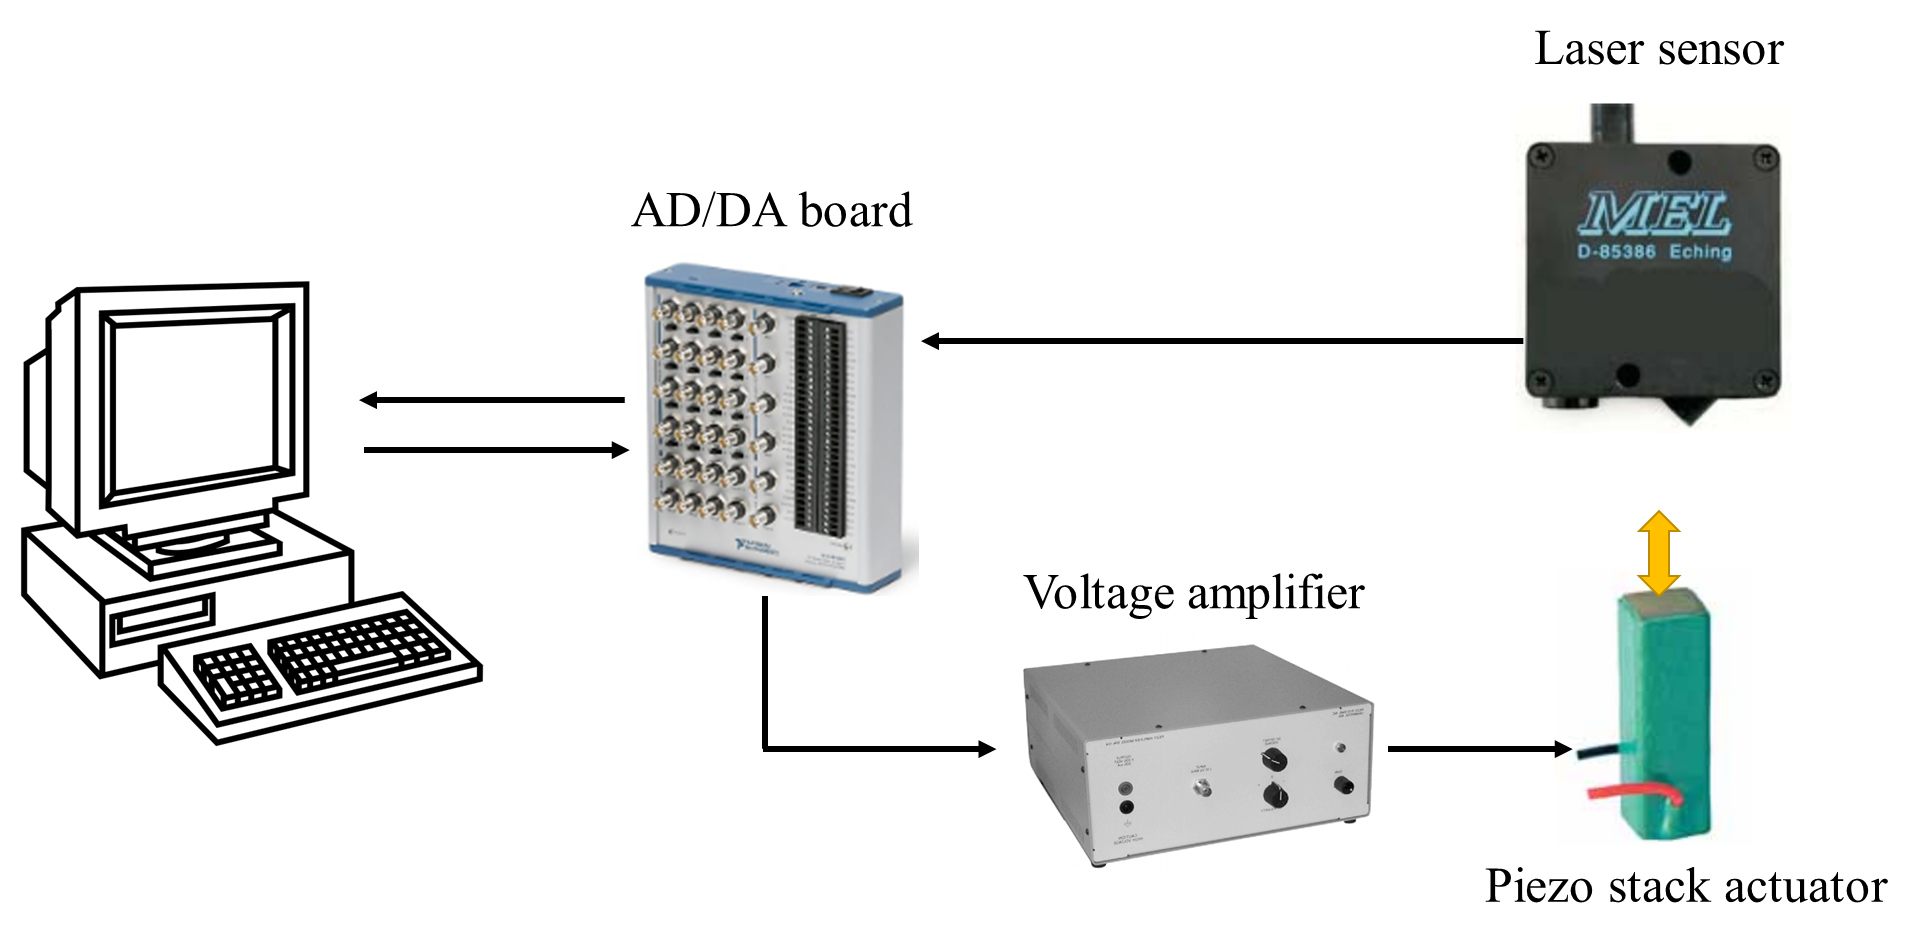

**Figure 1** – Schematic of the testing setup.

- **The task is to estimate the actuator gain **$\mathit{\mathbf{G}}$** using the following equation:**

### 
$$\mathit{\mathbf{d}}=\mathit{\mathbf{G}}\cdot \mathit{\mathbf{v}}$$


- **In this equation, **$\mathit{\mathbf{v}}$** is the applied voltage and **$\mathit{\mathbf{d}}$** is the displacement of the actuator. **

- **To estimate **$\mathit{\mathbf{G}}$**, we excite the actuator with known voltage **$\mathit{\mathbf{v}}$** and measure the resulting displacement **$\mathit{\mathbf{d}}$ **with the laser sensor.**

- **Load the datafile:** In the script below, load the “data1.mat” datafile. This file contains applied voltages $\mathit{\mathbf{v}}$ (in Volts) and the measured resulting displacements $\mathit{\mathbf{d}}$ (in μm).

- **Estimate:** Use the provided data and the above-mentioned equation to estimate $\mathit{\mathbf{G}}$.

- **Plot the data points and fitted function: **Plot the data points $\left(\mathit{\mathbf{v}},\mathit{\mathbf{d}}\right)$. On the same figure, plot the fitted function, $\mathit{\mathbf{d}}=\mathit{\mathbf{G}}\cdot \mathit{\mathbf{v}}$, for $\mathit{\mathbf{v}}$ within the range [0,100] Volts.

- **Predict:** Predict the value of $\mathit{\mathbf{d}}$ when $\mathit{\mathbf{v}}$ = 75 Volts.

**Hints****: **

- For estimation and prediction, you may use either MATLAB’s Curve Fitting Toolbox or the functions [**polyfit**](https://se.mathworks.com/help/matlab/ref/polyfit.html) and [**polyval**](https://se.mathworks.com/help/matlab/ref/polyval.html).

- If you decide to use Curve Fitting Toolbox, save the Toolbox-generated code in a separate script named "createFit1.m" and call it from the script below to estimate $\mathit{\mathbf{G}}$.

clear

load('data1.mat'); % Load the datafile

p = polyfit(v, d, 1); % since it's a linear relation, we use 1 as the degree of polynomial
% Plotting
figure;
plot(v, d, 'ro', 'DisplayName', 'Data points'); % plot the data points
hold on;

% Generate values for the fitted function
v_fit = 0:100;
d_fit = polyval(p, v_fit);

plot(v_fit, d_fit, 'b-', 'DisplayName', 'Estimated'); % plot the fitted function
xlabel('v (Volts)');
ylabel('d (μm)');
legend('show');

d_predicted = polyval(p, 75);
fprintf('The predicted displacement for 75 Volts is %f μm\n', d_predicted);

The predicted displacement for 75 Volts is 11.573107 μm


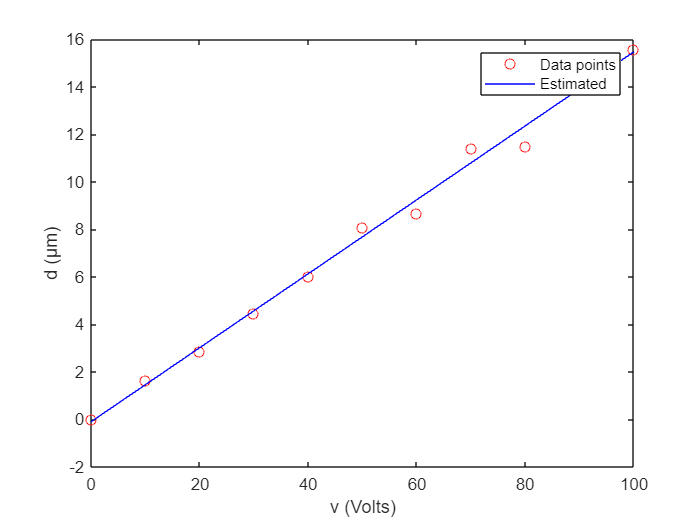


% Hold off the plotting
hold off;

%---------------------------------------------------------------

# **Problem 2 (3 points)**

- **Particle Tracking Velocimetry (PTV) is used to model the particle motion in field-based manipulation techniques.**

- **PTV employs a camera to track positions of particles frame by frame, compiling a dataset of initial positions and subsequent displacements of the particles.**

- **Figure 2A illustrates the application of PTV to a vibrating plate, enabling the collection of a training dataset of particle motion.**

- **The dataset includes training inputs, (**$\mathit{\mathbf{x}}$**, **$\mathit{\mathbf{y}}$**), representing the ****initial positions**** of particles, and training outputs, (**$\mathit{\mathbf{u}}$**, **$\mathit{\mathbf{v}}$**), representing their ****corresponding displacements in the X- and Y-directions**** (see Fig. 2B).**

- **The task is to model the particle displacements (**$\mathit{\mathbf{u}}$**, **$\mathit{\mathbf{v}}$**) as functions of the initial positions (**$\mathit{\mathbf{x}}$**, **$\mathit{\mathbf{y}}$**).**

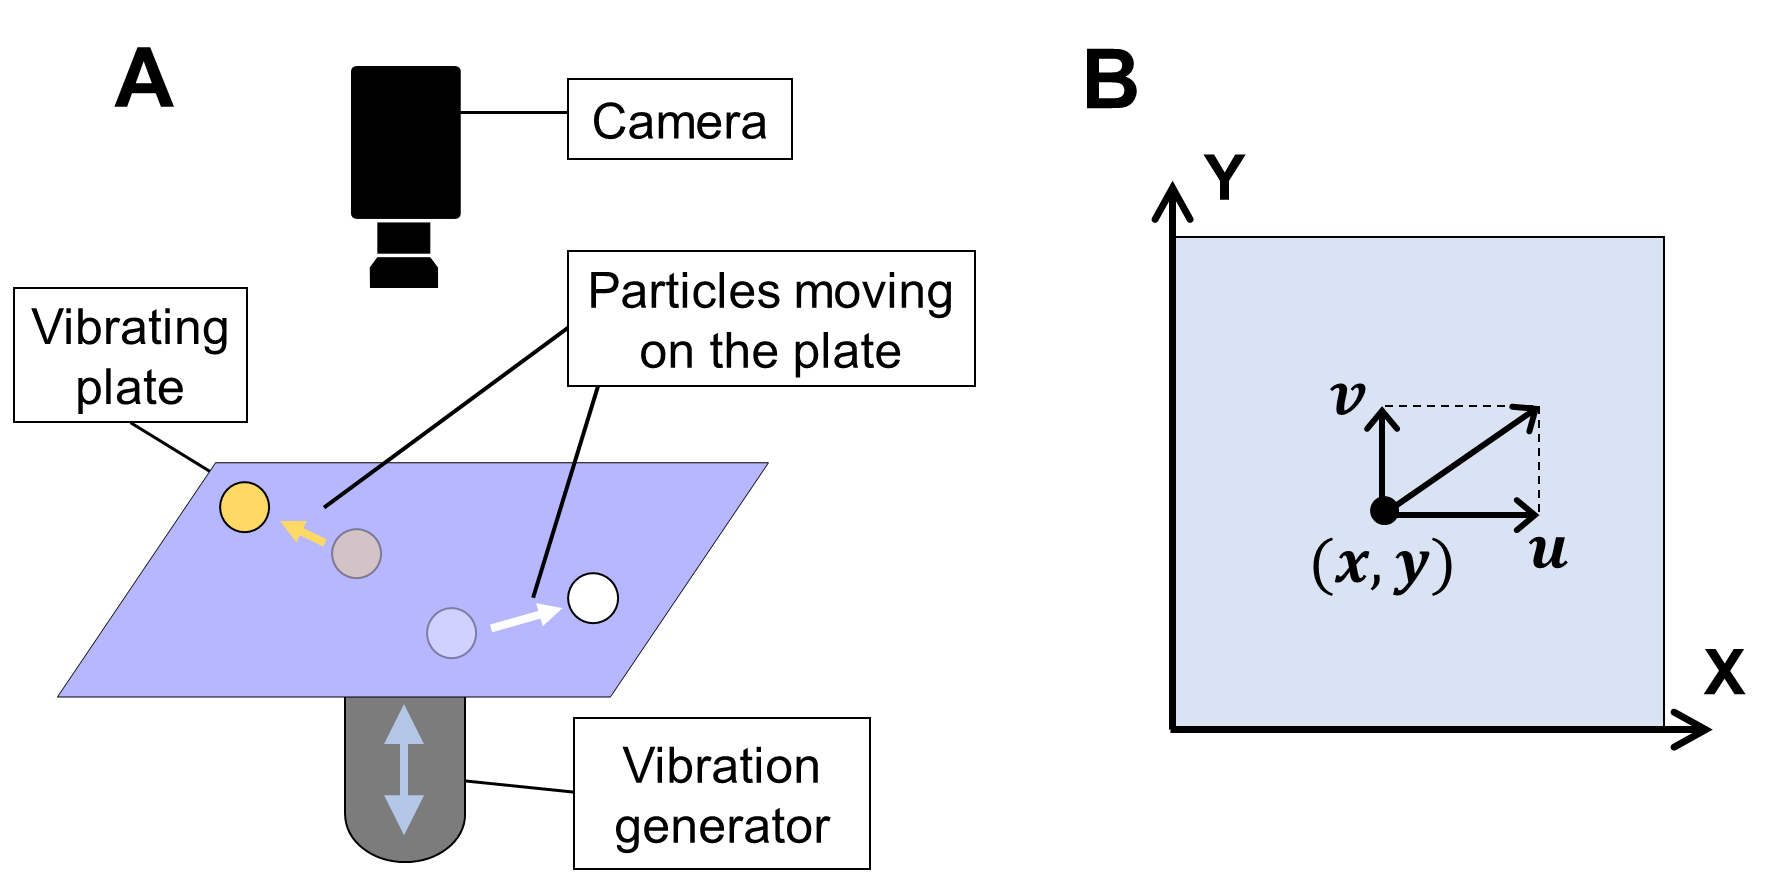

**Figure 2.** (**A**) PTV applied to a vibrating plate. (**B**) Particle motion on the plate: $\mathit{\mathbf{u}}$ and $\mathit{\mathbf{v}}$ are displacement components of a particle as functions of its initial position ($\mathit{\mathbf{x}}$**, **$\mathit{\mathbf{y}}$).

- **Load the datafile: **In the script below, load the “data2.mat” datafile. The file contains training inputs, $\mathit{\mathbf{x}}$ and $\mathit{\mathbf{y}}$, and training outputs, $\mathit{\mathbf{u}}$ and $\mathit{\mathbf{v}}$.

- **Fit: **Use MATLAB’s Curve Fitting Toolbox to fit polynomial surfaces $\mathit{\mathbf{f}}$ and $\mathit{\mathbf{g}}$ to the data. In the toolbox, presume 2nd-order polynomials for both fitted functions, $\mathit{\mathbf{u}}=\mathit{\mathbf{f}}\left(\mathit{\mathbf{x}},\mathit{\mathbf{y}}\right)$ and $\mathit{\mathbf{v}}=\mathit{\mathbf{g}}\left(\mathit{\mathbf{x}},\mathit{\mathbf{y}}\right)$. Save the Toolbox-generated code in a separate script, named "createFit2.m". **(1.5 points)**

- **Predict: **For $\mathit{\mathbf{x}}$ and $\mathit{\mathbf{y}}$ in the grid space [0,1] (see the code below), predict values of $\mathit{\mathbf{u}}$ and $\mathit{\mathbf{v}}$. **(0.75 points)**

- **Visualize: **Use a [**quiver plot**](https://se.mathworks.com/help/matlab/ref/quiver.html) to visualize the predictions. **(0.75 points)**

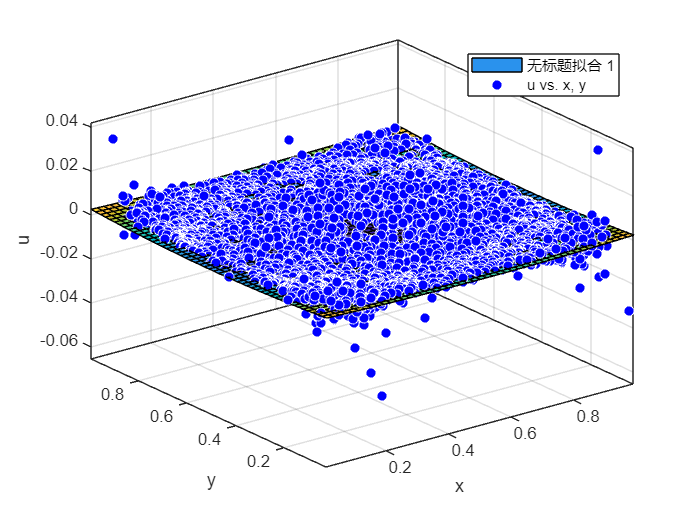

clear

load('data2.mat'); % Load the datafile

[gridx,gridy] = meshgrid(0:0.05:1,0:0.05:1); % Grid space of x and y for predicting u and v


%---------------------------------------------------------------
% Fit the polynomial surfaces to the data
[fitresult_u] = createFit2(x, y, u); % Assuming your data variables are named X, Y, uData, and vData in data2.mat

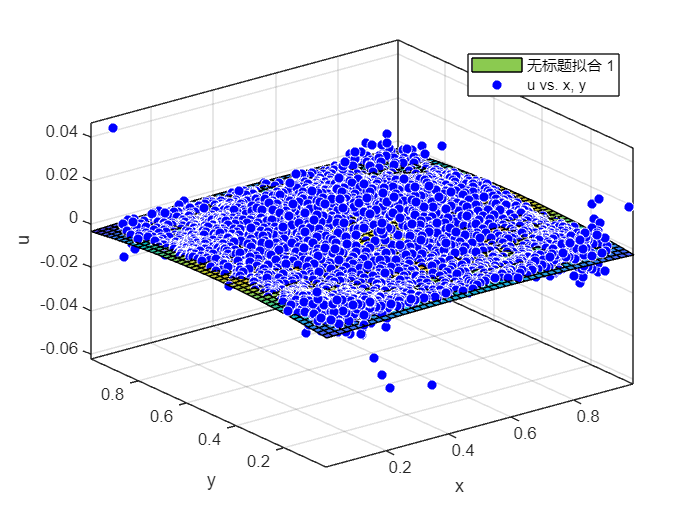

[fitresult_v] = createFit2(x, y, v);

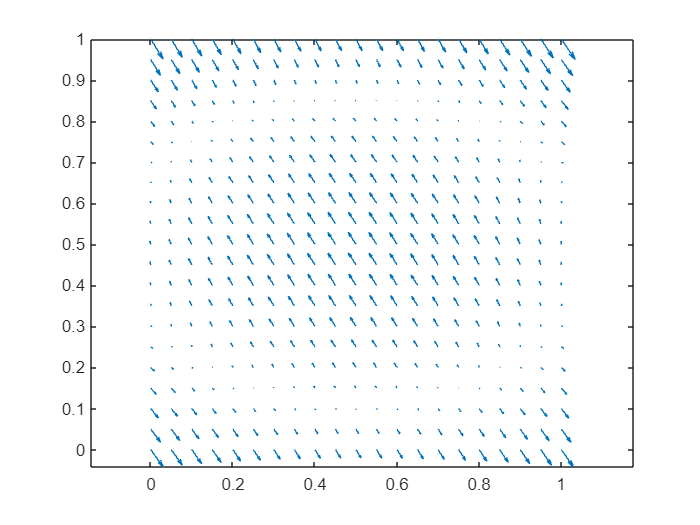

predict_u= fitresult_u(gridx,gridy);
predict_v= fitresult_v(gridx,gridy);
quiver(gridx,gridy,predict_u,predict_v);
axis equal

%---------------------------------------------------------------

# **Problem 3 (3.25 points)**

- **Load the datafile: **In the script below, load the “data3.mat” datafile. The file contains training inputs **x** and outputs **y**, and validation inputs and **xv** and outputs **yv**.

- **Estimate: **Using the training data and the closed-form solution, estimate the parameters $k_i$ of the following function:

## 
$$y=k_1 x^{k_2 }$$


              Note that you are not allowed to use MATLAB’s Curve Fitting Toolbox for this task. **(1.25 points)**

          3. **Visualize: **Make a [**scatter plot**](https://se.mathworks.com/help/matlab/ref/scatter.html) of the (**x**, **y**) and (**xv**, **yv**) data. On the same figure, plot the estimated function for **x** within the range [0,15]. **(0.5 points)**

          4. **Goodness of fit**: Compute the Sum of Squared Errors (SSE) and the coefficient of determination ($R^2$) for the training data. Additionally, calculate the SSE for the validation data. **(0.5 points)**

          5. **Alternative models: **Use functions [**polyfit**](https://se.mathworks.com/help/matlab/ref/polyfit.html) and [**polyval**](https://se.mathworks.com/help/matlab/ref/polyval.html) to fit polynomial models (of 1st, 2nd, 3rd, and 4th order) to the provided data. Which polynomial order would you select for this dataset, and why? **(1 point)**

clear

load('data3.mat'); % Load the datafile


%---------------------------------------------------------------
X=log(x);
Y=log(y);
coefficients = polyfit(X, Y, 1); % since it's a linear relation, we use 1 as the degree of polynomial
k_2 = coefficients(1);
k_1 = exp(coefficients(2));
% Plotting
figure;
plot(xv, yv, 'bo', 'DisplayName', 'Validation data points'); % plot the data points
hold on;
plot(x, y, 'ro', 'DisplayName', 'Training data points'); % plot the data points
hold on;

% Generate values for the fitted function
x_range = 0:15;
y_estimated=k_1*x_range.^k_2

plot(x_range, y_estimated, 'b-', 'DisplayName', 'Estimated'); % plot the fitted function
xlabel('x');
ylabel('y');
legend('show');
y_hat = k_1 * x.^k_2;

y_estimated =          0    2.0668    5.1656    8.8273   12.9104   17.3383   22.0621   27.0470   32.2668   37.7012   43.3336   49.1503   55.1397   61.2919   67.5983   74.0513


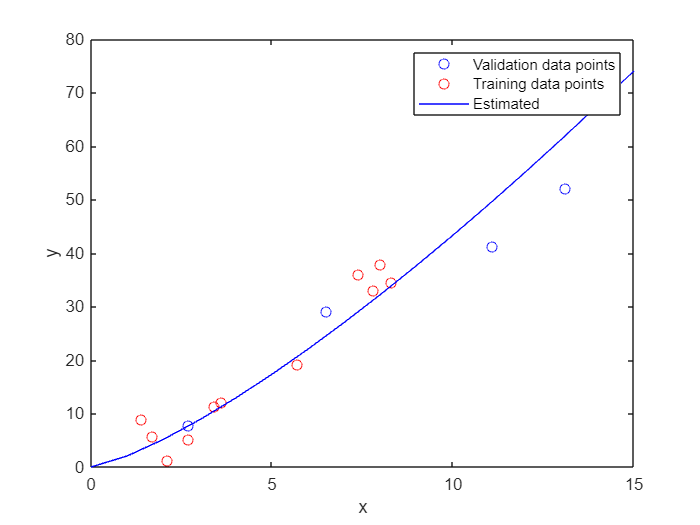

SSE_train = sum((y - y_hat).^2)
y_mean = mean(y);
R2 = 1 - SSE_train/sum((y - y_mean).^2)

y_hat_val = k_1 * xv.^k_2;

SSE_val = sum((yv - y_hat_val).^2)
orders = 1:4;

SSE_train = 144.2769

SSEs = zeros(size(orders));
for i = 1:length(orders)

R2 = 0.9267

    p = polyfit(x, y, orders(i));
    y_hat_poly = polyval(p,xv);
    SSEs(i) = sum((yv - y_hat_poly).^2);

SSE_val = 191.3184

end
SSEs
[~, best_order_idx] = min(SSEs);
best_order = orders(best_order_idx)
% I will choose the order 1, because the order that has the minimum SSE on the validation data, which provides the best fit without overfitting the training data.
%---------------------------------------------------------------

# **Problem 4 (2.5 points)**

**The task is to estimate the parameters **${\mathit{\mathbf{k}}}_{\mathit{\mathbf{i}}}$** of the following nonlinear function:**

## 
$$z=k_1 \left(1-e^{k_2 t} \right)$$


- **Load the datafile: **In the script below, load the “data4.mat” datafile. The file contains inputs **t** and outputs **z**.

- **Implement least squares: **Implement a cost function "computeCost.m" in a different script to calculate the Sum of Squared Errors (SSE) between the data points and the fitted function. The cost function takes the parameters $\mathit{\mathbf{k}}$ as an input and returns the value of SSE as an output. **(1 point)**

- **Estimate: **Estimate the parameters, ${\mathit{\mathbf{k}}}_1$ and ${\mathit{\mathbf{k}}}_2$, of the above stated function by minimizing the "computeCost" using the function [**fminsearch**](https://se.mathworks.com/help/matlab/ref/fminsearch.html) and the provided data. Initialize the search with the following values: ${\mathit{\mathbf{k}}}_1 =1$ and ${\mathit{\mathbf{k}}}_2 =1$. **(0.75 points)**

- **Visualize** the cost function near its global minimum.** Hint:** Use the [**surf**](https://se.mathworks.com/help/matlab/ref/surf.html) function to do so. **(0.75 points)**

clear

SSEs = 1.0e+03 *

    0.1454    1.8801    4.7373    0.4369



load('data4.mat'); % Load the datafile

best_order = 1


global t z % Declare the variables as global to enable computeCost access them
% Initial parameter guesses
initial_params = [1, 1];

% Define the anonymous function for fminsearch
costFunctionHandle = @(params) computeCost(params, t, z);

% Use fminsearch to estimate the parameters
estimated_params = fminsearch(costFunctionHandle, initial_params)

k1_estimated = estimated_params(1);

k2_estimated = estimated_params(2);

% Define ranges for k1 and k2 based on estimated values
k1_range = linspace(k1_estimated - 0.05, k1_estimated + 0.1, 100);
k2_range = linspace(k2_estimated - 0.1, k2_estimated + 0.1, 100);

% Preallocate cost values
J_vals = zeros(length(k1_range), length(k2_range));

estimated_params =     1.4927   -0.2021


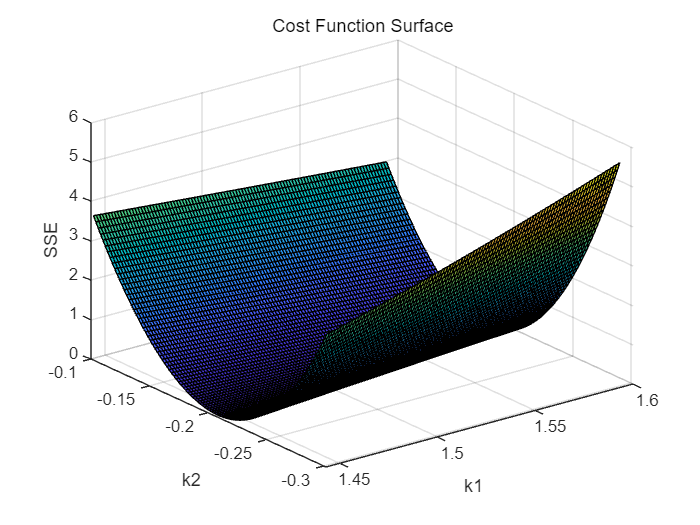


% Calculate cost for each combination of k1 and k2
for i = 1:length(k1_range)
    for j = 1:length(k2_range)
        J_vals(i, j) = computeCost([k1_range(i), k2_range(j)], t, z);
    end
end

% Plot the surface
[K1, K2] = meshgrid(k1_range, k2_range);
surf(K1, K2, J_vals');
xlabel('k1');
ylabel('k2');
zlabel('SSE');
title('Cost Function Surface');


%---------------------------------------------------------------


# **What to return?**

You are expected to submit your assignment to the related link for Assignment 3 in MyCourses.

Your submission should include:

- One completed .mlx file: **Assignment_3_*your_student_number*.mlx**

- MATLAB script:** createFit1.m **(optional)

- MATLAB script:** createFit2.m**

- MATLAB script:** computeCost.m**